indigoData = readtable('all_data.xlsx');
dataFiles = indigoData.Filename(~indigoData.EcoliModelExclusive);

valMethod = 'cv';
K = 5;
standardize = 'standardized';
modelType = 2;
input_type = 2;

for i = 2:length(dataFiles)
    testData = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training da

Results for ecoli_mg1655_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         35         0.48599      0.0034209    0.54286        0.45714                 0.8               0.44444        

averagesTable = 11×1 table
                                Value  
                              _________

    Interactions                   34.4
    R (rank)                    0.56439
    P value                   0.0024461
    Accuracy                    0.52286
    Absolute error              0.50067
    Precision (synergy)            0.66
    Recall (synergy)            0.47416
    Precision (antagonism)         0.59
    Recall (antagonism)         0.38222
    AUC - ROC (synergy)         0.29933
    AUC - ROC (antagonism)      0.74764


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     172
    R (rank)                     0.57325
    P value                   2.0659e-16
    Accuracy                     0.52326
    Absolute error                   0.5
    Precision (synergy)             0.66
    Recall (synergy)             0.47143
    Precision (antagonism)        0.6087
    Recall (antagonism)          0.37838
    AUC - ROC (synergy)          0.30511
    AUC - ROC (antagonism)       0.74114


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to trainin

Results for s_aureus_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9           0.26667    0.49333    0.22222        0.88889                  0.2                 0.5                  

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    9
    R (rank)                  0.27333
    P value                   0.50495
    Accuracy                  0.53333
    Absolute error            0.55556
    Precision (synergy)       0.50714
    Recall (synergy)             0.81
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)       0.34857
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   45
    R (rank)                  0.17511
    P value                   0.24992
    Accuracy                  0.53333
    Absolute error            0.55556
    Precision (synergy)       0.48276
    Recall (synergy)          0.82353
    Precision (antagonism)        NaN
    Recall (antagonism)             0
    AUC - ROC (synergy)       0.35609
    AUC - ROC (antagonism)    0.54323


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to training

Results for mtb_h37rv_chandrasekaran_2016

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5              NaN         NaN       0.8            0.2                   0                    NaN                 

averagesTable = 11×1 table
                              Value
                              _____

    Interactions               4.6 
    R (rank)                   NaN 
    P value                    NaN 
    Accuracy                  0.63 
    Absolute error            0.37 
    Precision (synergy)        NaN 
    Recall (synergy)           NaN 
    Precision (antagonism)     NaN 
    Recall (antagonism)        NaN 
    AUC - ROC (synergy)        NaN 
    AUC - ROC (antagonism)     NaN 


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     23
    R (rank)                    0.63772
    P value                   0.0010621
    Accuracy                    0.65217
    Absolute error              0.34783
    Precision (synergy)             0.6
    Recall (synergy)                0.5
    Precision (antagonism)            1
    Recall (antagonism)             0.4
    AUC - ROC (synergy)         0.27941
    AUC - ROC (antagonism)      0.78333


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to traini

Results for ecoli_bw25113_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         64         0.80458              0     0.8125        0.28125                  0.8                 0.96        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                    63.4
    R (rank)                     0.65614
    P value                   0.00011308
    Accuracy                      0.7252
    Absolute error               0.43914
    Precision (synergy)          0.71494
    Recall (synergy)             0.84773
    Precision (antagonism)       0.88112
    Recall (antagonism)          0.66262
    AUC - ROC (synergy)          0.17458
    AUC - ROC (antagonism)       0.81348


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     317
    R (rank)                     0.67089
    P value                   8.3072e-43
    Accuracy                     0.72555
    Absolute error               0.43849
    Precision (synergy)          0.72109
    Recall (synergy)             0.85484
    Precision (antagonism)       0.87943
    Recall (antagonism)           0.6631
    AUC - ROC (synergy)          0.17195
    AUC - ROC (antagonism)       0.81547


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to tra

Results for ecoli_iAi1_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         63         0.69484              0    0.71429        0.38095              0.72222              0.54167        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                    63.2
    R (rank)                     0.68965
    P value                   5.9111e-09
    Accuracy                     0.75947
    Absolute error               0.36711
    Precision (synergy)          0.80812
    Recall (synergy)             0.69463
    Precision (antagonism)       0.88179
    Recall (antagonism)          0.81859
    AUC - ROC (synergy)          0.14944
    AUC - ROC (antagonism)       0.85027


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     316
    R (rank)                     0.68641
    P value                   2.3842e-45
    Accuracy                     0.75949
    Absolute error               0.36709
    Precision (synergy)          0.81301
    Recall (synergy)              0.6993
    Precision (antagonism)        0.8805
    Recall (antagonism)          0.81871
    AUC - ROC (synergy)          0.14885
    AUC - ROC (antagonism)       0.85108


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx t

Results for stlt2_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         50         0.78756              0       0.86            0.2                 0.85                 0.85        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                    49.8
    R (rank)                     0.74226
    P value                   2.6604e-07
    Accuracy                     0.82727
    Absolute error               0.26922
    Precision (synergy)          0.88933
    Recall (synergy)              0.7898
    Precision (antagonism)       0.88058
    Recall (antagonism)          0.88132
    AUC - ROC (synergy)          0.11485
    AUC - ROC (antagonism)       0.88828


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                    249
    R (rank)                    0.73497
    P value                   1.466e-43
    Accuracy                    0.82731
    Absolute error              0.26908
    Precision (synergy)         0.88889
    Recall (synergy)            0.78571
    Precision (antagonism)       0.8806
    Recall (antagonism)          0.8806
    AUC - ROC (synergy)         0.11581
    AUC - ROC (antagonism)      0.88855


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to t

Results for st14028s_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         50         0.60182     6.0347e-06      0.72           0.44               0.79167              0.86364        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                      50
    R (rank)                     0.62468
    P value                   0.00015116
    Accuracy                       0.764
    Absolute error                 0.356
    Precision (synergy)          0.83322
    Recall (synergy)             0.83485
    Precision (antagonism)       0.83501
    Recall (antagonism)          0.74573
    AUC - ROC (synergy)            0.143
    AUC - ROC (antagonism)       0.82765


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     250
    R (rank)                     0.65073
    P value                   1.7094e-31
    Accuracy                       0.764
    Absolute error                 0.356
    Precision (synergy)          0.83178
    Recall (synergy)             0.83962
    Precision (antagonism)       0.83471
    Recall (antagonism)          0.74815
    AUC - ROC (synergy)           0.1362
    AUC - ROC (antagonism)       0.83366


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx 

Results for pao1_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         32         0.45088      0.01023    0.65625        0.59375              0.66667              0.61538              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                 32.6
    R (rank)                  0.29802
    P value                   0.13952
    Accuracy                  0.58277
    Absolute error            0.72386
    Precision (synergy)       0.64169
    Recall (synergy)          0.50117
    Precision (antagonism)    0.65195
    Recall (antagonism)       0.66091
    AUC - ROC (synergy)        0.3588
    AUC - ROC (antagonism)    0.63033


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     163
    R (rank)                     0.30666
    P value                   6.8509e-05
    Accuracy                     0.58282
    Absolute error               0.72393
    Precision (synergy)          0.63636
    Recall (synergy)                 0.5
    Precision (antagonism)       0.65217
    Recall (antagonism)          0.65934
    AUC - ROC (synergy)          0.35906
    AUC - ROC (antagonism)        0.6292


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx 

Results for pa14_brochado_2018

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         33           0.499      0.0034865    0.63636        0.57576                  0.6              0.81818        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                    32.6
    R (rank)                     0.61811
    P value                   0.00077905
    Accuracy                     0.70587
    Absolute error               0.42803
    Precision (synergy)          0.72573
    Recall (synergy)             0.79133
    Precision (antagonism)       0.83549
    Recall (antagonism)          0.71926
    AUC - ROC (synergy)          0.17942
    AUC - ROC (antagonism)       0.81591


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     163
    R (rank)                     0.61551
    P value                   2.2729e-18
    Accuracy                     0.70552
    Absolute error               0.42945
    Precision (synergy)          0.73333
    Recall (synergy)              0.7971
    Precision (antagonism)       0.83333
    Recall (antagonism)          0.71429
    AUC - ROC (synergy)          0.17761
    AUC - ROC (antagonism)       0.81397


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to 

Results for ecoli_mg1655_yeh_2006

resultsTable = 5×11 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         31         0.32932      0.070437    0.45161        0.58065              0.33333              0.28571           

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                    31
    R (rank)                   0.39736
    P value                   0.037114
    Accuracy                   0.45161
    Absolute error             0.63871
    Precision (synergy)        0.39111
    Recall (synergy)           0.37881
    Precision (antagonism)      0.6358
    Recall (antagonism)        0.60531
    AUC - ROC (synergy)        0.33396
    AUC - ROC (antagonism)     0.71607


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     155
    R (rank)                     0.41359
    P value                   8.8499e-08
    Accuracy                     0.45161
    Absolute error               0.63871
    Precision (synergy)          0.39535
    Recall (synergy)             0.37778
    Precision (antagonism)       0.63158
    Recall (antagonism)              0.6
    AUC - ROC (synergy)          0.33596
    AUC - ROC (antagonism)       0.71123


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to trainin

Results for ecoli_mc4100_bliss_russ_2018

resultsTable = 5×11 table
                Interactions     R (rank)     P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    __________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         16            0.16765    0.53389     0.3125              1              0.33333              0.28571           

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   16
    R (rank)                  0.15353
    P value                   0.60621
    Accuracy                   0.2875
    Absolute error               1.05
    Precision (synergy)       0.25667
    Recall (synergy)          0.16071
    Precision (antagonism)    0.37167
    Recall (antagonism)       0.46667
    AUC - ROC (synergy)       0.62294
    AUC - ROC (antagonism)    0.53679


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   80
    R (rank)                  0.12382
    P value                   0.27385
    Accuracy                   0.2875
    Absolute error               1.05
    Precision (synergy)       0.28571
    Recall (synergy)          0.15385
    Precision (antagonism)    0.36364
    Recall (antagonism)       0.44444
    AUC - ROC (synergy)       0.63446
    AUC - ROC (antagonism)    0.51922


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to trainin

Results for ecoli_mc4100_loewe_russ_2018

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         16         -0.29412     0.26807      0.125          1.125                    0                    0              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   16
    R (rank)                  0.20647
    P value                   0.31904
    Accuracy                    0.275
    Absolute error              0.925
    Precision (synergy)       0.41238
    Recall (synergy)             0.35
    Precision (antagonism)    0.22667
    Recall (antagonism)          0.23
    AUC - ROC (synergy)       0.41921
    AUC - ROC (antagonism)    0.42682


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   80
    R (rank)                  0.16351
    P value                   0.14728
    Accuracy                    0.275
    Absolute error              0.925
    Precision (synergy)       0.41379
    Recall (synergy)          0.36364
    Precision (antagonism)    0.28571
    Recall (antagonism)       0.22222
    AUC - ROC (synergy)       0.42263
    AUC - ROC (antagonism)    0.43501


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to tra

Results for ecoli_mg1655_fatsis_2020

Index exceeds the number of array elements (16).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD

%finish running rest, redo fatsis with k=3 after
for i = 15:length(dataFiles)
    testData = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to tra

Results for ecoli_mg1655_katzir_2019

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         32         0.65707     4.4054e-05    0.65625            0.5              0.64286              0.64286        

averagesTable = 11×1 table
                                Value   
                              __________

    Interactions                      32
    R (rank)                     0.68393
    P value                   2.5394e-05
    Accuracy                     0.66875
    Absolute error                0.4625
    Precision (synergy)          0.73838
    Recall (synergy)              0.6196
    Precision (antagonism)       0.80587
    Recall (antagonism)          0.76801
    AUC - ROC (synergy)          0.21813
    AUC - ROC (antagonism)       0.82373


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     160
    R (rank)                     0.67201
    P value                   2.2906e-22
    Accuracy                     0.66875
    Absolute error                0.4625
    Precision (synergy)          0.73684
    Recall (synergy)             0.61765
    Precision (antagonism)           0.8
    Recall (antagonism)          0.76923
    AUC - ROC (synergy)          0.22387
    AUC - ROC (antagonism)        0.8202


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for ecoli_bw25113_ocampo_2014

resultsTable = 5×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         29         0.70781     1.7494e-05    0.62069        0.41379                  0.7              0.63636        

averagesTable = 11×1 table
                                Value  
                              _________

    Interactions                   29.6
    R (rank)                     0.5194
    P value                   0.0090951
    Accuracy                    0.48069
    Absolute error              0.58713
    Precision (synergy)         0.61974
    Recall (synergy)            0.64625
    Precision (antagonism)      0.52955
    Recall (antagonism)         0.49835
    AUC - ROC (synergy)         0.23499
    AUC - ROC (antagonism)      0.71405


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                     148
    R (rank)                      0.5071
    P value                   4.8027e-11
    Accuracy                     0.47973
    Absolute error               0.58784
    Precision (synergy)          0.61818
    Recall (synergy)             0.62963
    Precision (antagonism)           0.5
    Recall (antagonism)              0.5
    AUC - ROC (synergy)          0.24291
    AUC - ROC (antagonism)       0.70684


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for a_baumannii_cokol_2018

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9           0.74478    0.026268    0.66667        0.33333                    1                    1              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    9
    R (rank)                  0.30353
    P value                   0.21684
    Accuracy                  0.46667
    Absolute error            0.75556
    Precision (synergy)       0.78333
    Recall (synergy)             0.55
    Precision (antagonism)    0.59286
    Recall (antagonism)          0.44
    AUC - ROC (synergy)       0.30333
    AUC - ROC (antagonism)       0.65


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    45
    R (rank)                    0.3064
    P value                   0.040649
    Accuracy                   0.46667
    Absolute error             0.75556
    Precision (synergy)        0.73333
    Recall (synergy)              0.55
    Precision (antagonism)     0.55556
    Recall (antagonism)        0.43478
    AUC - ROC (synergy)          0.323
    AUC - ROC (antagonism)     0.62154


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_yilancioglu_2019_mtb

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         21         0.075325     0.74539    0.61905         0.7619              0.55556              0.55556              

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                   21
    R (rank)                   0.3374
    P value                   0.21995
    Accuracy                  0.71429
    Absolute error            0.57143
    Precision (synergy)       0.62778
    Recall (synergy)          0.56373
    Precision (antagonism)    0.78112
    Recall (antagonism)       0.78962
    AUC - ROC (synergy)       0.32333
    AUC - ROC (antagonism)    0.67667


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                    105
    R (rank)                    0.33679
    P value                   0.0004432
    Accuracy                    0.71429
    Absolute error              0.57143
    Precision (synergy)         0.57143
    Recall (synergy)            0.57143
    Precision (antagonism)      0.78571
    Recall (antagonism)         0.78571
    AUC - ROC (synergy)         0.32143
    AUC - ROC (antagonism)      0.67857


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_h37rv_1_nicole_mtb

Index exceeds the number of array elements (4).

Error in internal.stats.corrSpearman>pvalSpearman (line 246)
        p(t) = tailProb(2*D(t)+1); % bins at half integers, starting at zero

Error in internal.stats.corrSpearman (line 162)
                pval = pvalSpearman(tail,D,meanD,

%fatsis data, K=3
valMethod = 'cv';
K = 3;
standardize = 'standardized';
modelType = 2;
input_type = 2;


testData = dataFiles{14};
trainingData = dataFiles([1:14-1 14+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to training data
Adding ecoli_bw25113_ocampo_2014.xlsx to tra

[stats,averages,overview] = analyze(indigoSummary);

Results for ecoli_mg1655_fatsis_2020

resultsTable = 3×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         4             0.4         0.75        1              0                  NaN                  NaN                   

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                4.3333
    R (rank)                       0.1
    P value                    0.72778
    Accuracy                   0.93333
    Absolute error            0.066667
    Precision (synergy)            NaN
    Recall (synergy)               NaN
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)         NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    13
    R (rank)                    0.2628
    P value                    0.38569
    Accuracy                   0.92308
    Absolute error            0.076923
    Precision (synergy)            NaN
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            0.5
    AUC - ROC (antagonism)         NaN


save(saveIndigo(indigoSummary))

%mtb nicole, m_abscesses, K=2
valMethod = 'cv';
K = 2;
standardize = 'standardized';
modelType = 2;
input_type = 2;


for i = 19:22
    testData = dataFiles{i};
    trainingData = dataFiles([1:i-1 i+1:end]);
    indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);
    [stats,averages,overview] = analyze(indigoSummary);
    save(saveIndigo(indigoSummary))
end

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_h37rv_1_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5          -0.57735      0.4          1              0                  NaN                  NaN                   

averagesTable = 11×1 table
                               Value  
                              ________

    Interactions                     5
    R (rank)                  -0.72472
    P value                       0.25
    Accuracy                       0.9
    Absolute error                 0.1
    Precision (synergy)            NaN
    Recall (synergy)               NaN
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            NaN
    AUC - ROC (antagonism)         NaN


overviewTable = 11×1 table
                               Value  
                              ________

    Interactions                    10
    R (rank)                  -0.76155
    P value                   0.010485
    Accuracy                       0.9
    Absolute error                 0.1
    Precision (synergy)            NaN
    Recall (synergy)                 0
    Precision (antagonism)         NaN
    Recall (antagonism)            NaN
    AUC - ROC (synergy)            0.5
    AUC - ROC (antagonism)         NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_h37rv_2_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         9          0.97468     0.00013228    0.77778        0.22222                NaN                  NaN          

averagesTable = 11×1 table
                                Value  
                              _________

    Interactions                      9
    R (rank)                    0.91396
    P value                   0.0020503
    Accuracy                    0.77778
    Absolute error              0.22222
    Precision (synergy)             NaN
    Recall (synergy)                NaN
    Precision (antagonism)          NaN
    Recall (antagonism)               0
    AUC - ROC (synergy)             NaN
    AUC - ROC (antagonism)          0.5


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      18
    R (rank)                     0.89699
    P value                   4.5934e-07
    Accuracy                     0.77778
    Absolute error               0.22222
    Precision (synergy)              NaN
    Recall (synergy)                 NaN
    Precision (antagonism)           NaN
    Recall (antagonism)                0
    AUC - ROC (synergy)              NaN
    AUC - ROC (antagonism)           0.5


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for mtb_h37rv_3_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         6          -0.20292    0.72222    0.83333        0.16667                 0                   NaN                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  5.5
    R (rank)                  0.04854
    P value                   0.70278
    Accuracy                  0.71667
    Absolute error            0.28333
    Precision (synergy)             0
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                                Value  
                              _________

    Interactions                     11
    R (rank)                  -0.027652
    P value                     0.93568
    Accuracy                    0.72727
    Absolute error              0.27273
    Precision (synergy)               0
    Recall (synergy)                  0
    Precision (antagonism)          NaN
    Recall (antagonism)             NaN
    AUC - ROC (synergy)             0.6
    AUC - ROC (antagonism)          NaN


Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for m_abscessus_nicole_mtb

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         3            0.5          1       0.66667        0.33333                  0                  NaN                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    3
    R (rank)                      0.5
    P value                         1
    Accuracy                  0.66667
    Absolute error            0.33333
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                    6
    R (rank)                  0.23191
    P value                   0.66667
    Accuracy                  0.66667
    Absolute error            0.33333
    Precision (synergy)             0
    Recall (synergy)                0
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           0.6
    AUC - ROC (antagonism)        NaN


%m_smegmatis
valMethod = 'cv';
K = 5;
standardize = 'standardized';
modelType = 2;
input_type = 2;


testData = dataFiles{23};
trainingData = dataFiles([1:23-1 23+1:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

[stats,averages,overview] = analyze(indigoSummary);

Results for m_smegmatis_nicole_mtb

resultsTable = 5×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5              0.8     0.13333        0.8            0.2                NaN                    0                   

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  5.2
    R (rank)                  0.45429
    P value                   0.35722
    Accuracy                  0.85333
    Absolute error            0.14667
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                                Value   
                              __________

    Interactions                      26
    R (rank)                     0.65146
    P value                   0.00031226
    Accuracy                     0.84615
    Absolute error               0.15385
    Precision (synergy)              NaN
    Recall (synergy)                   0
    Precision (antagonism)           NaN
    Recall (antagonism)              NaN
    AUC - ROC (synergy)              0.5
    AUC - ROC (antagonism)           NaN


save(saveIndigo(indigoSummary))

%confusion matrices for m_abscessus, m_smegmatis
valMethod = 'cv';
K = 2;
standardize = 'standardized';
modelType = 2;
input_type = 2;

testData = dataFiles{22};
trainingData = dataFiles([1:22-1 i+22:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for m_abscessus_nicole_mtb

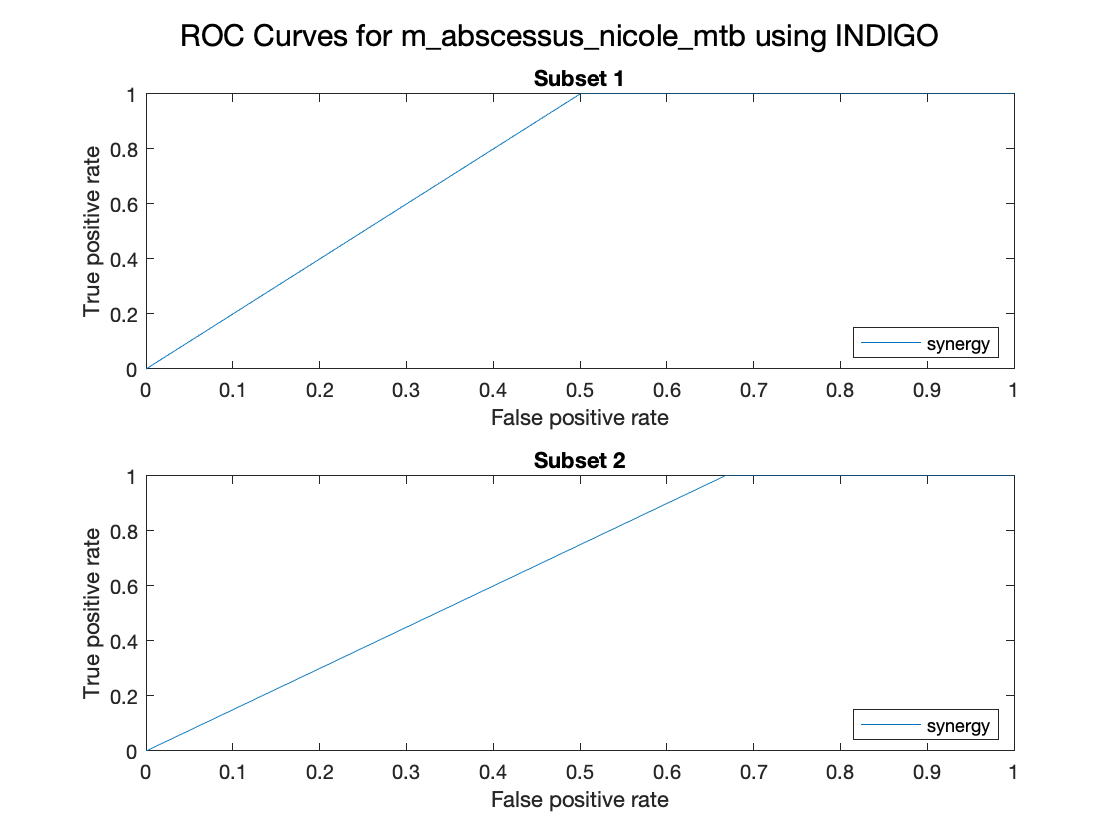

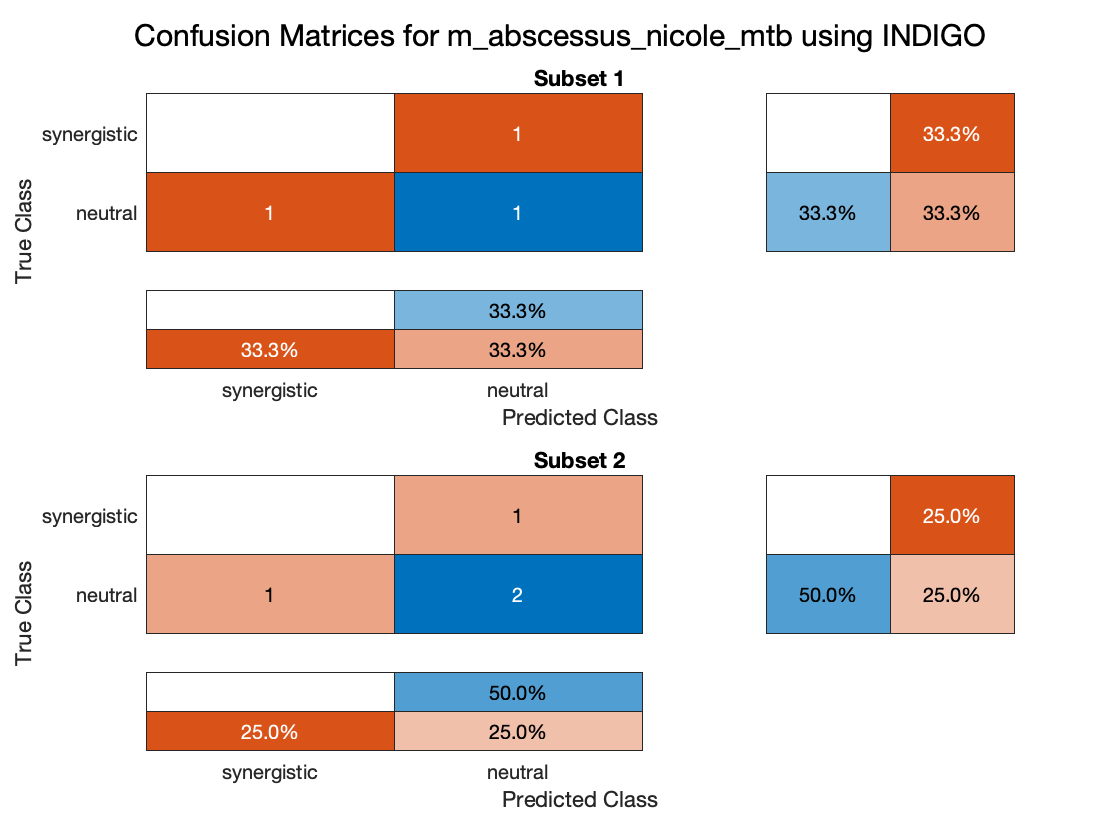

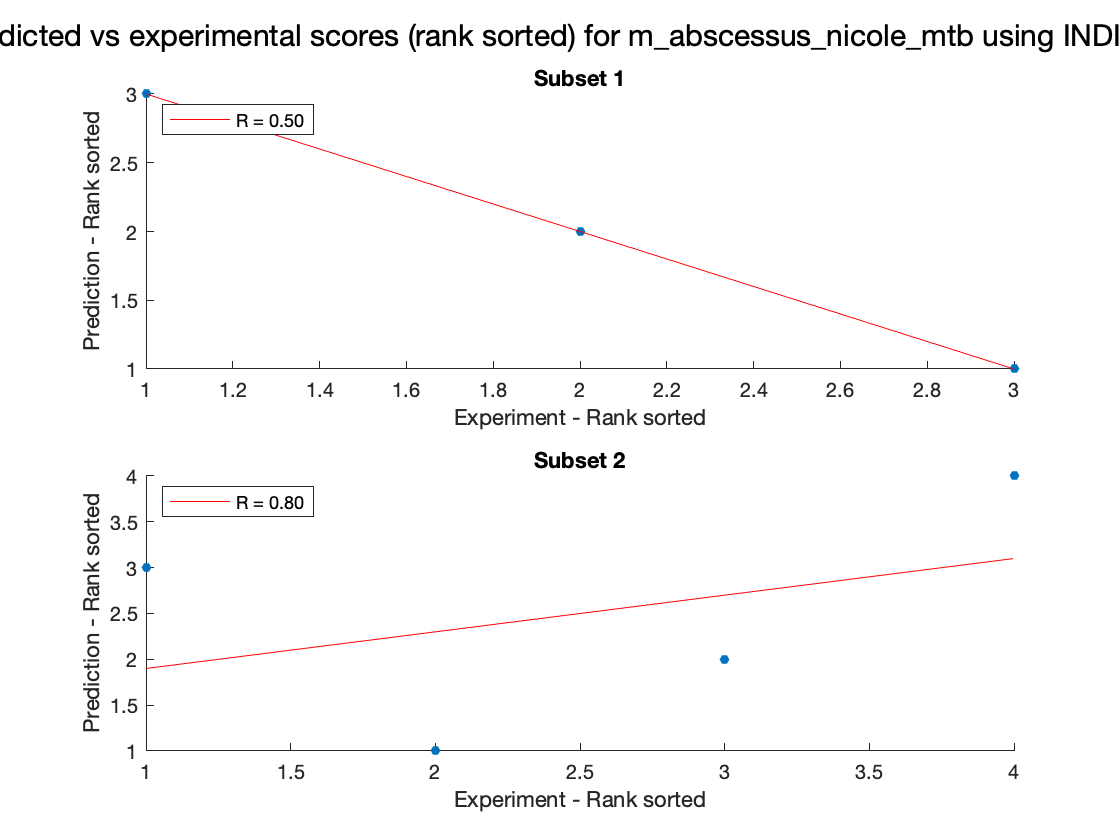

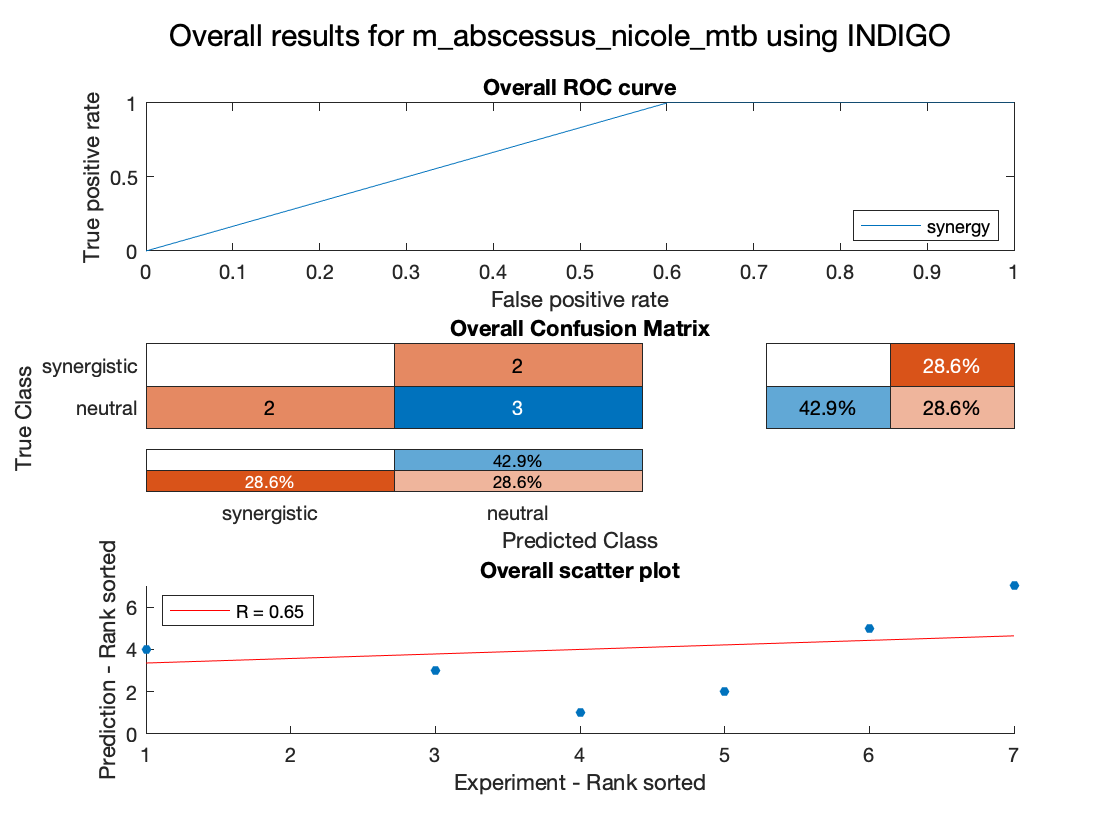

resultsTable = 2×11 table
                Interactions    R (rank)    P value    Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _______    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         3            0.5             1    0.33333        0.66667                 0                    0                    

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                  3.5
    R (rank)                     0.65
    P value                   0.66667
    Accuracy                  0.41667
    Absolute error            0.58333
    Precision (synergy)             0
    Recall (synergy)                0
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)       0.70833
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                    7
    R (rank)                  0.65465
    P value                    0.1254
    Accuracy                  0.42857
    Absolute error            0.57143
    Precision (synergy)             0
    Recall (synergy)                0
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           0.7
    AUC - ROC (antagonism)        NaN


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

K=5;
testData = dataFiles{23};
trainingData = dataFiles([1:23-1 i+23:end]);
indigoSummary = indigoRun(testData,trainingData,valMethod,K,standardize,modelType,input_type);

Found 8 batches
Adjusting for 0 covariate(s) or covariate level(s)
Standardizing Data across voxels/genes/FCs
Fitting L/S model and finding priors
Finding parametric adjustments
Adjusting the Data
Adding mtb_h37rv_ma_2019_mtb.xlsx to training data
Adding ecoli_mg1655_chandrasekaran_2016.xlsx to training data
Adding s_aureus_chandrasekaran_2016.xlsx to training data
Adding mtb_h37rv_chandrasekaran_2016.xlsx to training data
Adding ecoli_bw25113_brochado_2018.xlsx to training data
Adding ecoli_iAi1_brochado_2018.xlsx to training data
Adding stlt2_brochado_2018.xlsx to training data
Adding st14028s_brochado_2018.xlsx to training data
Adding pao1_brochado_2018.xlsx to training data
Adding pa14_brochado_2018.xlsx to training data
Adding ecoli_mg1655_yeh_2006.xlsx to training data
Adding ecoli_mc4100_bliss_russ_2018.xlsx to training data
Adding ecoli_mc4100_loewe_russ_2018.xlsx to training data
Adding ecoli_mg1655_fatsis_2020.xlsx to training data
Adding ecoli_mg1655_katzir_2019.xlsx to trai

Results for m_smegmatis_nicole_mtb

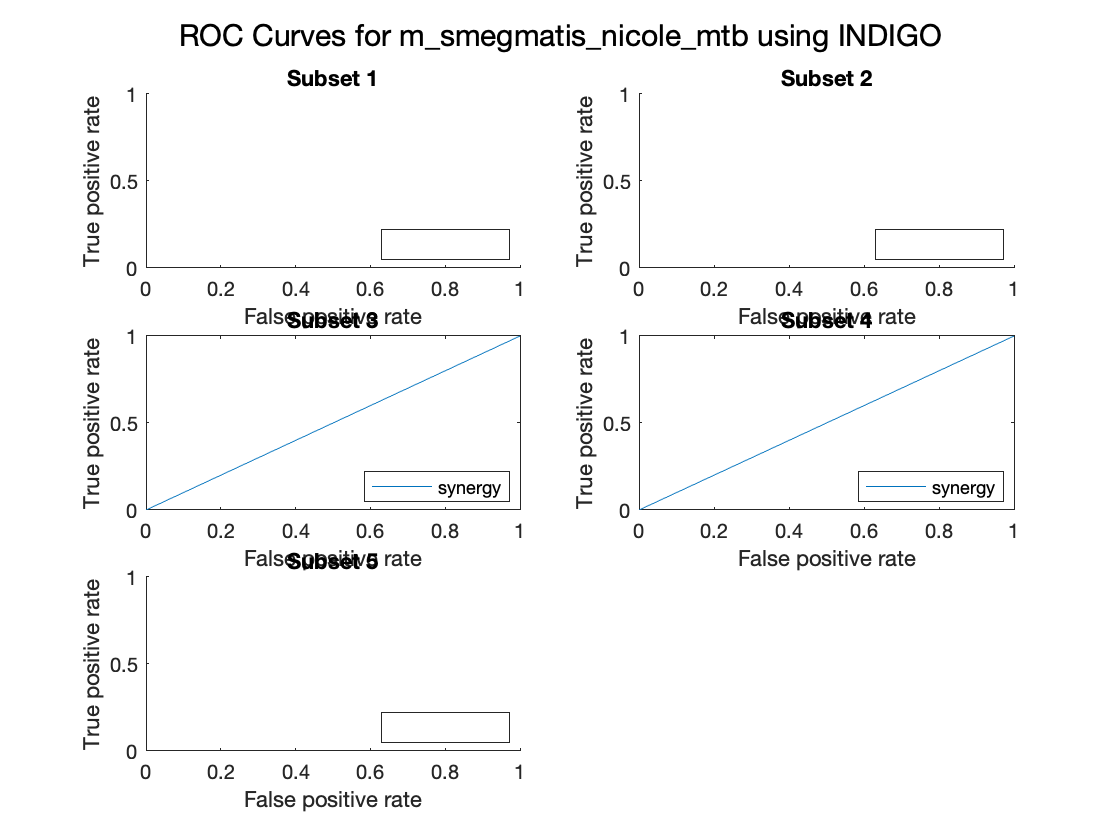

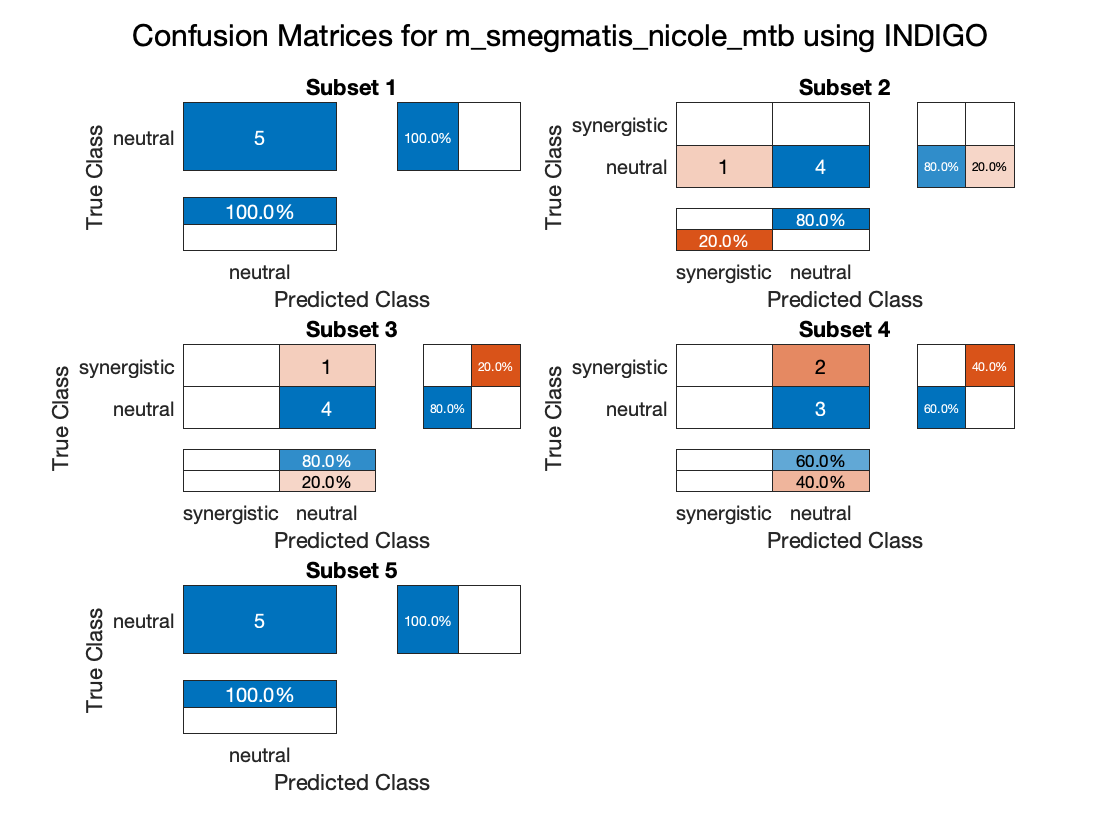

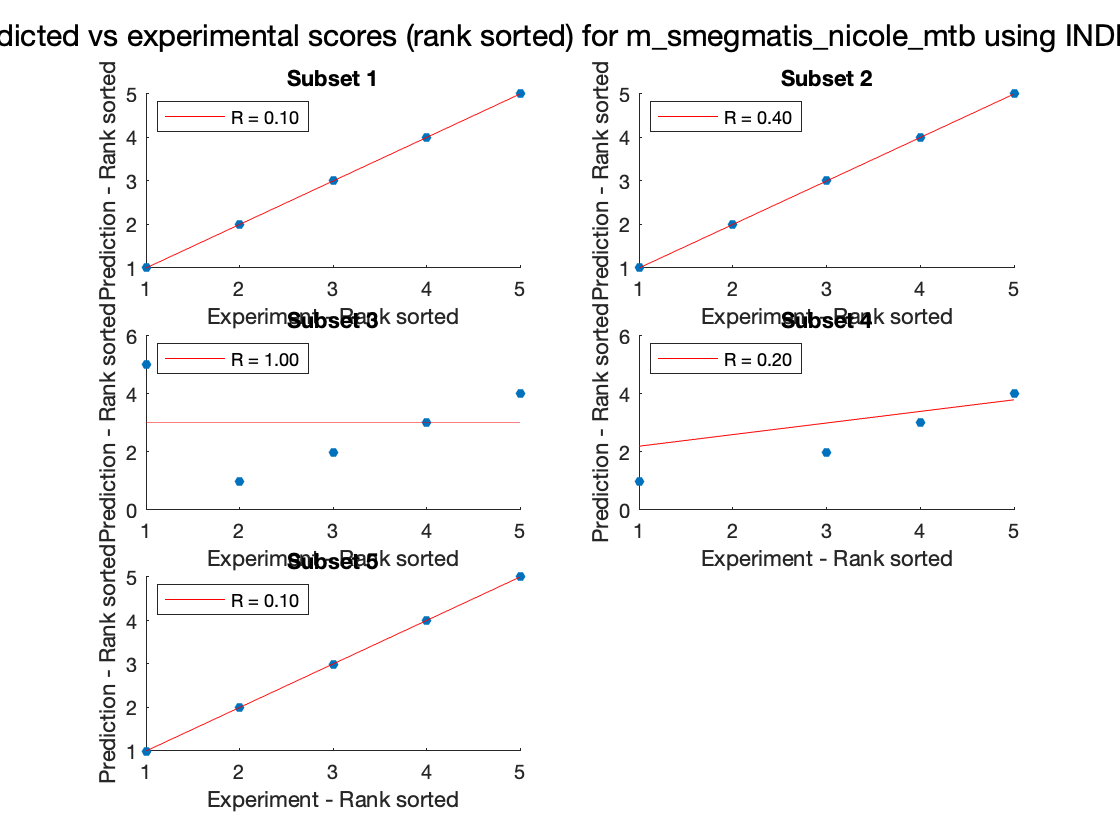

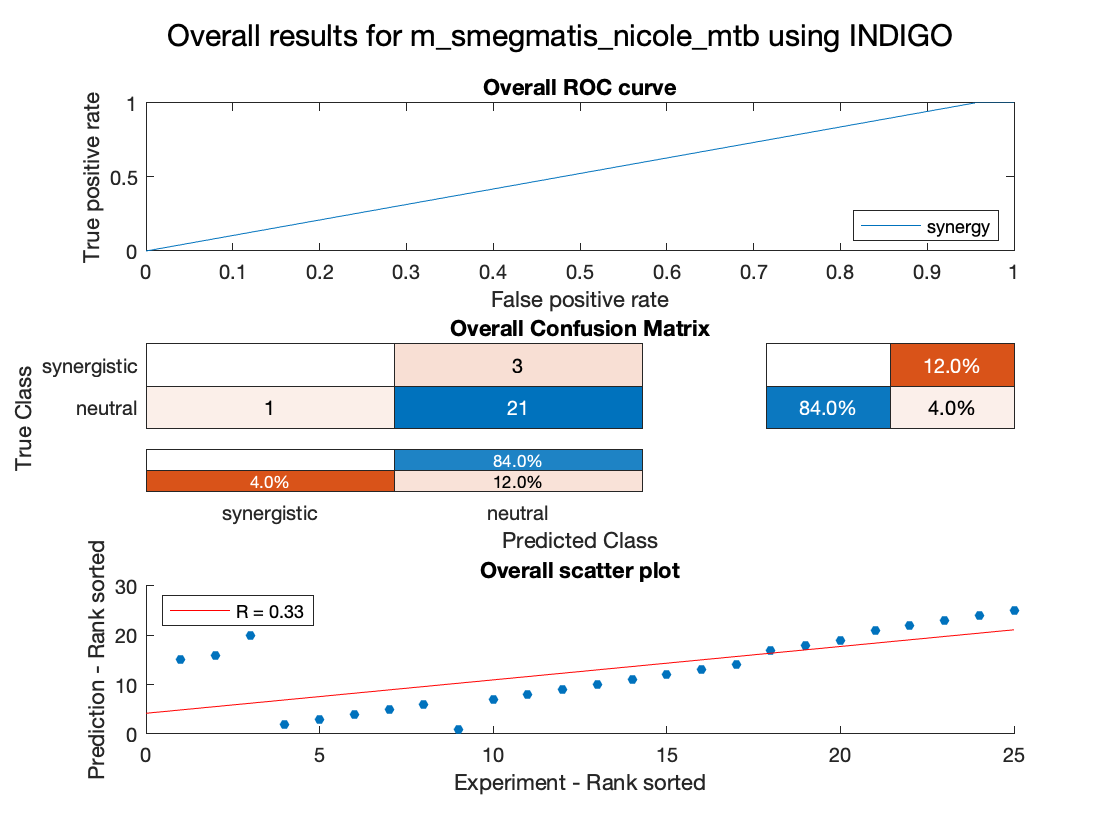

resultsTable = 5×11 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ___________________    ______________________

    Subset 1         5            0.1           0.95        1              0                  NaN                  NaN                

averagesTable = 11×1 table
                               Value 
                              _______

    Interactions                    5
    R (rank)                     0.36
    P value                   0.64333
    Accuracy                     0.84
    Absolute error               0.16
    Precision (synergy)           NaN
    Recall (synergy)              NaN
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)           NaN
    AUC - ROC (antagonism)        NaN


overviewTable = 11×1 table
                               Value 
                              _______

    Interactions                   25
    R (rank)                  0.33012
    P value                   0.10704
    Accuracy                     0.84
    Absolute error               0.16
    Precision (synergy)             0
    Recall (synergy)                0
    Precision (antagonism)        NaN
    Recall (antagonism)           NaN
    AUC - ROC (synergy)       0.52273
    AUC - ROC (antagonism)        NaN


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))